
socbound = out.soc_bound.Data;
sochat = out.soc_hat.Data;
soc = out.soc.Data;
time = out.tout;

fprintf('RMS SOC estimation error = %g%%\n',sqrt(mean((100*(soc-sochat)).^2)));

RMS SOC estimation error = 3.19475%


ind = find(abs(soc-sochat)>socbound);
fprintf('Percent of time error outside bounds = %g%%\n',length(ind)/length(soc)*100);

Percent of time error outside bounds = 0%


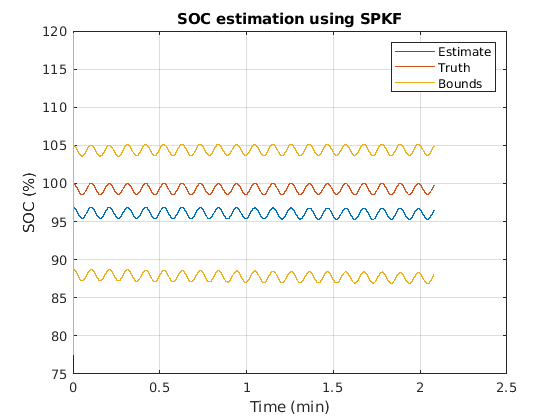



f1 = figure(1);clf;
plot(time/60,100*sochat,time/60,100*soc); hold on
plot([time/60; NaN; time/60],[100*(sochat+socbound); NaN; 100*(sochat-socbound)]);
title('SOC estimation using SPKF'); grid on
xlabel('Time (min)'); ylabel('SOC (%)'); legend('Estimate','Truth','Bounds');
hold off;

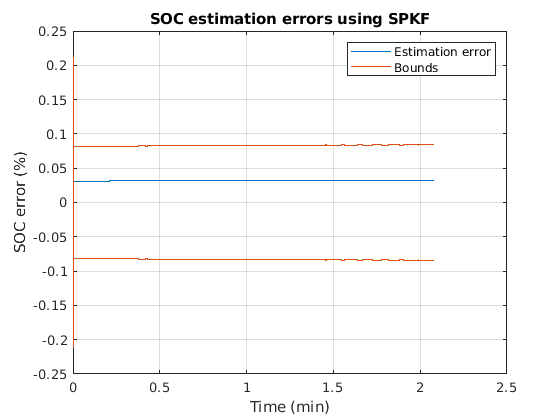


f2 = figure(2); clf;
plot(time/60,(soc-sochat)); hold on
plot([time/60; NaN; time/60],[socbound; NaN; -socbound]);
title('SOC estimation errors using SPKF');
xlabel('Time (min)'); ylabel('SOC error (%)'); 
legend('Estimation error','Bounds'); 
grid on;
hold off;